start EEGLAB

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m


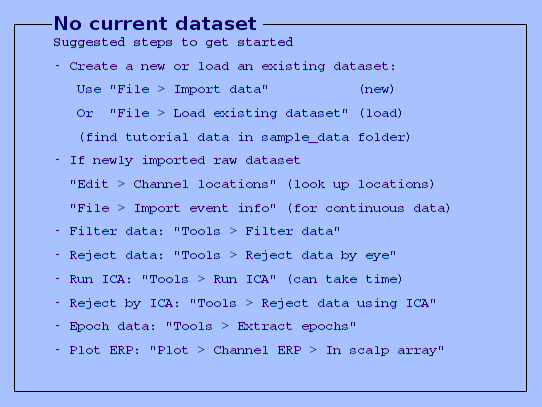

Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "bva-io" v1.6 (see >> help eegplugin_bva_io)
EEGLAB: adding "dipfit" v3.0 (see >> help eegplugin_dipfit) - new version 3.4 available
EEGLAB: adding "firfilt" v2.1 (see >> help eegplugin_firfilt) - new version 2.4 available
EEGLAB: adding "musemonitor" v3.1 (see >> help eegplugin_musemonitor) - new version 3.2 available
You are using the latest version of EEGLAB.


eeglab;

Load existing study from sample_data eeglab folder:

[STUDY ALLEEG] = pop_loadstudy('filename', 'n400clustedit.study', 'filepath', '/home/claire/Applications/eeglab/sample_data/5subjects');

pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/5subjects/s02/syn02-s253-clean.set ...
pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/5subjects/s05/syn05-s253-clean.set ...
pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/5subjects/s07/syn07-s253-clean.set ...
pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/5subjects/s08/syn08-s253-clean.set ...
pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/5subjects/s10/syn10-s253-clean.set ...
pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/5subjects/s02/syn02-s254-clean.set ...
pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/5subjects/s05/syn05-s254-clean.set ...
pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/5subjects/s07/syn07-s254-clean.set ...
pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/5subjects/s08/syn08-s254-clean.


CURRENTSTUDY = 1; EEG = ALLEEG; CURRENTSET = [1:length(EEG)];

Compute ERP measure for the STUDY set. 

[STUDY ALLEEG] = std_precomp(STUDY, ALLEEG, {},'savetrials','on', ...
'interp','on',... % interpolate missing channels
'recompute','on',... % recompute measure if already present
'erp','on',... % compute ERPs
'erpparams',{'rmbase' [-300 0] }); %specify ERP baseline

Reading float file '/home/claire/Applications/eeglab/sample_data/5subjects/s02/syn02-s253-clean.dat'...
Reading float file '/home/claire/Applications/eeglab/sample_data/5subjects/s02/syn02-s254-clean.dat'...
Removing baseline...
Saving ERP file '/home/claire/Applications/eeglab/sample_data/5subjects/s02/S02.daterp'
Reading float file '/home/claire/Applications/eeglab/sample_data/5subjects/s05/syn05-s253-clean.dat'...
Reading float file '/home/claire/Applications/eeglab/sample_data/5subjects/s05/syn05-s254-clean.dat'...
Removing baseline...
Saving ERP file '/home/claire/Applications/eeglab/sample_data/5subjects/s05/S05.daterp'
Reading float file '/home/claire/Applications/eeglab/sample_data/5subjects/s07/syn07-s253-clean.dat'...
Reading float file '/home/claire/Applications/eeglab/sample_data/5subjects/s07/syn07-s254-clean.dat'...
Removing baseline...
Saving ERP file '/home/claire/Applications/eeglab/sample_data/5subjects/s07/S07.daterp'
Reading float file '/home/claire/Applications/eeg

Specify statistical parameters

STUDY  = pop_statparams(STUDY,... 
'condstats','on',... % perform stats on 1st independant variable
'method','perm',... % use perumtation method
'mcorrect','fdr',...% correct for multiple comparisons using fdr
'alpha',0.01); %specify statistical threshold


Plot ERP time course

Reading subjects' data or looking up measure values in EEGLAB cache
.....
1 x 2, paired data, computing T values
Using paired t-test
Permutations (of 4000):...
Applying FDR correction for multiple comparisons


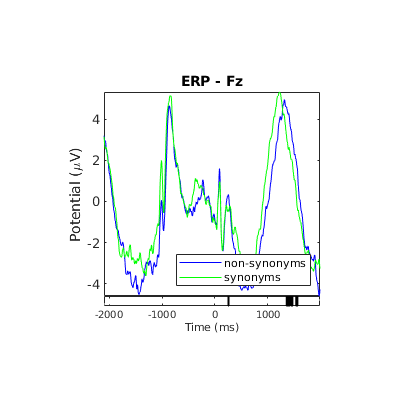

STUDY = pop_erpparams(STUDY, 'plotconditions','together'); % specify plot parameters
STUDY = std_erpplot(STUDY,ALLEEG,'channels',{'Fz'}, 'design', 1); %select channel to plot and STUDY design

Plot ERP topographic map

Reading subjects' data or looking up measure values in EEGLAB cache
.....
1 x 2, paired data, computing T values
Using paired t-test
Permutations (of 4000):...
Applying FDR correction for multiple comparisons


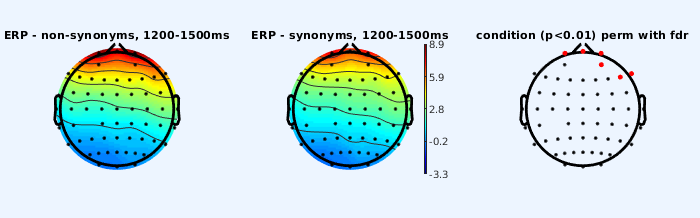

STUDY = pop_erpparams(STUDY, 'topotime',[1200 1500] ); %specify the time range to plot the topomap
STUDY = std_erpplot(STUDY,ALLEEG,'channels',{'Fp1' 'Fpz' 'Fp2' 'AF3' 'AF4' 'F7' 'F5' 'F3' 'F1' 'Fz' 'F2' 'F4' 'F6' 'F8' 'FC5' 'FC3' 'FC1' 'FCz' 'FC2' 'FC4' 'FC6' 'T7' 'C5' 'C3' 'C1' 'Cz' 'C2' 'C4' 'C6' 'T8' 'CP1' 'CPz' 'CP2' 'CP4' 'CP6' 'TP8' 'P7' 'P5' 'P3' 'P1' 'Pz' 'P2' 'P4' 'P6' 'P8' 'PO5' 'PO3' 'PO1' 'POz' 'PO2' 'PO4' 'PO6' 'O1' 'Oz' 'O2' 'LO1' 'IO1' 'SO1' 'LO2' 'TP7' 'CP5'}, 'design', 1);

Plot the difference between two conditions

We specify erpdata and erptimes to retrieve these measures from the outputs of std_erplot - lookup the help of this function for more details

Reading subjects' data or looking up measure values in EEGLAB cache
.....
1 x 2, paired data, computing T values
Using paired t-test
Permutations (of 4000):...
Applying FDR correction for multiple comparisons


[STUDY erpdata erptimes] = std_erpplot(STUDY,ALLEEG,'channels',{'Fp1' 'Fpz' 'Fp2' 'AF3' 'AF4' 'F7' 'F5' 'F3' 'F1' 'Fz' 'F2' 'F4' 'F6' 'F8' 'FC5' 'FC3' 'FC1' 'FCz' 'FC2' 'FC4' 'FC6' 'T7' 'C5' 'C3' 'C1' 'Cz' 'C2' 'C4' 'C6' 'T8' 'CP1' 'CPz' 'CP2' 'CP4' 'CP6' 'TP8' 'P7' 'P5' 'P3' 'P1' 'Pz' 'P2' 'P4' 'P6' 'P8' 'PO5' 'PO3' 'PO1' 'POz' 'PO2' 'PO4' 'PO6' 'O1' 'Oz' 'O2' 'LO1' 'IO1' 'SO1' 'LO2' 'TP7' 'CP5'}, 'design', 1);

The erpdata variable is organized condition x channels x subjects:

erpdata

erpdata = 2×1 cell array
    {1×61×5 single}
    {1×61×5 single}


We get the difference between the 2 conditions:

diff_cond = erpdata{1}-erpdata{2}

diff_cond = 1×61×5 single array
diff_cond(:,:,1) =

    2.1588    1.4931    1.6279    1.1561    0.5927    1.1297    0.7060    0.6394    0.1424   -0.0737   -0.1507   -0.0818    0.2455    0.5186    0.2483   -0.2742   -0.3585   -0.6592   -0.7192   -0.5872   -0.2684   -0.0187   -0.2816   -0.8230   -0.8204   -1.2762   -1.4600   -1.2676   -1.0455   -0.4756   -1.1023   -1.4951   -1.6289   -1.5892   -1.2489   -0.8756   -0.4675   -0.9513   -0.9562   -1.2582   -1.4791   -1.5098   -1.4698   -1.2268   -0.7217   -0.4570   -0.8087   -1.0924   -1.3598   -1.4233   -1.1637   -0.6972   -0.5700   -0.5939   -0.6722    0.3947   -1.2410    3.1519   -0.7092   -0.5473   -0.9863


diff_cond(:,:,2) =

    1.0787    1.4562    1.5597    0.9480    1.3235    0.3669    0.9613    0.9356    0.9828    1.2959    1.2547    1.2410    1.4382    1.6002    0.6514    0.9652    1.2677    1.2477    1.1826    1.2660    1.1256    0.4120    0.5332    0.9327    0.9086    1.0237    1.1550    1.1179    0.7402    0.6017    0.8344    0